## **Exercises 19a and 19b**

Questo codice crea due sinusoidi con diverse configurazioni di spettro e le rappresenta graficamente nel dominio del tempo. 

La prima sinusoide utilizza lo spettro completo, mentre la seconda utilizza solo le frequenze positive.

### Definizione delle variabili di input

clear
clc

% define the input variables
Ndata1 = 16;                       % Number of data points in the first sine wave
Ampl = 1;                          % amplitude of the sine
phse = pi/2;                       % phase of the sine
fSample = 1000;                    % sample frequency defined in exercise n.17
fSine = fSample/Ndata1;            % frequency of the sinewave, chosen to avoid leakage
Ts = 1/fSample;                    % sample period
t = [0:Ndata1-1]*Ts;               % time vector

- `Ndata1` rappresenta il numero di punti dati nella prima sinusoide (16 in questo caso).

- `Ampl` rappresenta l'ampiezza della sinusoide (1 in questo caso).

- `phse` rappresenta la fase della sinusoide (π/2 in questo caso).

- `fSample` rappresenta la frequenza di campionamento (1000 Hz in questo caso).

- `fSine` rappresenta la frequenza della sinusoide, scelta in modo da evitare la perdita di informazioni durante la DFT. **fSine < fSample/2**

- `Ts` rappresenta il periodo di campionamento calcolato come l'inverso della frequenza di campionamento.

- `t` rappresenta un vettore di tempo che va da 0 a `Ndata1-1` moltiplicato per `Ts`, cioè l'intervallo di tempo tra i campioni.

### Parte 1 - Utilizzo dello spettro completo

% Part 1: using the full spectrum
U1 = zeros(Ndata1,1);             % create spectrum
U1(2) = exp(-j*phse);
U1(Ndata1) = exp(+j*phse);

u1 = ifft(U1)*Ndata1/2;           % IFFT inverse Fourier transform

In questa parte del codice viene utilizzato lo spettro completo per generare una sinusoide. 

Viene creato un vettore `U1` di zeri che rappresenta lo spettro, e poi vengono impostati gli elementi `2` e `Ndata1` di `U1` con valori complessi che rappresentano la fase della sinusoide.

Successivamente, viene eseguita l'inversa della trasformata di Fourier (`ifft`) di `U1` per ottenere il segnale nel dominio del tempo. 

Il risultato viene moltiplicato per `Ndata1/2` (viene normalizzato) e viene assegnato alla variabile `u1`.

### Parte 2 - Utilizzo delle sole frequenze positive

% Part 2: using only the positive frequencies
U2 = zeros(Ndata1,1);    % create spectrum
U2(2) = exp(-j*pi/2);

u2 = Ampl*2*real(ifft(U2))*Ndata1/2;            % inverse Fourier transform

In questa parte del codice viene utilizzato solo lo spettro delle frequenze positive per generare un'altra sinusoide. Viene creato un vettore `U2` di zeri che rappresenta lo spettro, e l'elemento `2` di `U2` viene impostato con un valore complesso che rappresenta la fase della sinusoide.

Successivamente, viene eseguita la trasformata di Fourier inversa (`ifft`) di `U2`, e il risultato viene moltiplicato per `Ampl*2` e `Ndata1/2` (viene normalizzato). 

Il risultato finale viene assegnato alla variabile `u2`.

### Stampa dei grafici

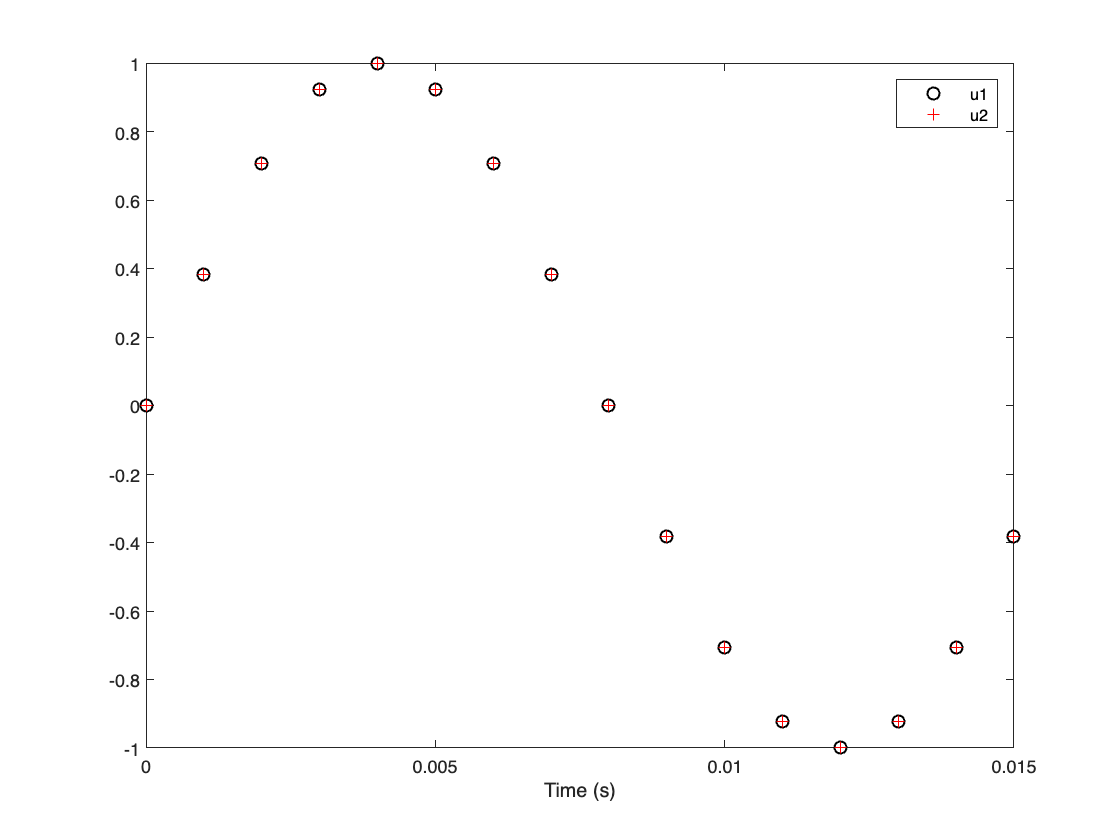

% plot the results
FigNum = 4;
figure(FigNum)
clf
plot(t, u1, 'ok', t, u2, '+r')
legend ('u1', 'u2')
DG_SetFontSize(9)
DG_SetTraceWidth(0.5, 2, FigNum)
DG_SetTraceWidth(1, 1, FigNum)
xlabel('Time (s)')

In questa sezione viene visualizzato il risultato delle due sinusoidi generate. 

Viene creata una nuova figura con il numero di figura `FigNum` (4 in questo caso) e vengono tracciati i punti `(t, u1)` come cerchi neri (`'ok'`) e i punti `(t, u2)` come croci rosse (`'+r'`).

Successivamente, vengono impostati il font size a 9 e lo spessore delle tracce. Infine, viene aggiunta un'etichetta sull'asse x con il testo "Time (s)".

### Esportazione dei grafici in formato PDF

% Export the plot
% DG_Init4PDF(gcf, 6);        % fixing the size, half standard height
% DG_MakePDF('FigSinus4.pdf', gcf);

Queste righe di codice contengono le istruzioni per esportare il grafico in un file PDF.

## Conclusioni

Il codice genera due sinusoidi utilizzando diverse configurazioni dello spettro e le rappresenta graficamente nel dominio del tempo. La prima sinusoide utilizza lo spettro completo, mentre la seconda utilizza solo le frequenze positive.

La trasformata di Fourier discreta (DFT) e la sua inversa, l'IFFT, richiedono calcoli intensivi e possono richiedere tempo e risorse computazionali considerevoli, specialmente per segnali di grandi dimensioni. Tuttavia, la DFT gode di proprietà simmetriche e, in particolare, lo spettro di un segnale reale nel dominio del tempo è simmetrico rispetto all'asse delle frequenze. Ciò significa che la metà negativa dello spettro può essere ricavata a partire dalla metà positiva senza effettuare ulteriori calcoli, riducendo, così, il costo computazionale necessario.

Per calcolare con un minimo sforzo numerico un segnale nel dominio del tempo a partire dal suo spettro, è possibile utilizzare l'istruzione MATLAB `u = N*(real(ifft(U)))`. È necessario definire solo la prima metà dello spettro, la seconda metà viene posta a zero.

E' importante notare che il risparmio di risorse può dipendere dalla dimensione del segnale e dall'implementazione specifica dell'algoritmo di calcolo della DFT o dell'IFFT. Per la generazione di un singolo seno, infatti, questo metodo non è molto efficiente dal punto di vista computazionale. Tuttavia, per una somma di sinusoidi armonicamente correlate con molte componenti, si ottiene un'enorme riduzione del tempo di calcolo. 

Inoltre, dato che l'`ifft` è una trasformazione ortogonale dal dominio della frequenza a quello del tempo, viene mantenuta la massima stabilità numerica.

### Appendice - Stabilità numerica nella Trasformata inversa di Fourier

Quando si utilizza la trasformata inversa di Fourier (IFFT o IDFT) per passare dal dominio della frequenza al dominio del tempo, si dice che è una **trasformazione ortogonale** perché preserva la norma del segnale.

La stabilità numerica si riferisce alla capacità di mantenere l'accuratezza dei calcoli numerici in presenza di errori di arrotondamento e approssimazione. Nella maggior parte delle implementazioni di algoritmi di trasformata di Fourier, inclusa l'IFFT, possono verificarsi errori numerici a causa delle limitazioni della rappresentazione dei numeri in virgola mobile.

Tuttavia, è importante notare che l'IFFT è una trasformazione invertibile e conserva l'energia del segnale originale. Pertanto, in termini di stabilità numerica, l'IFFT è considerata una trasformazione molto stabile perché mantiene l'informazione del segnale originale durante la conversione dal dominio della frequenza al dominio del tempo.

Ciò significa che l'utilizzo dell'IFFT per ricostruire un segnale nel dominio del tempo a partire dal suo spettro nel dominio della frequenza mantiene l'accuratezza dei calcoli e l'integrità del segnale originale.